Process for fitting UIR using the native calibration signal of XLTEK EEG system 

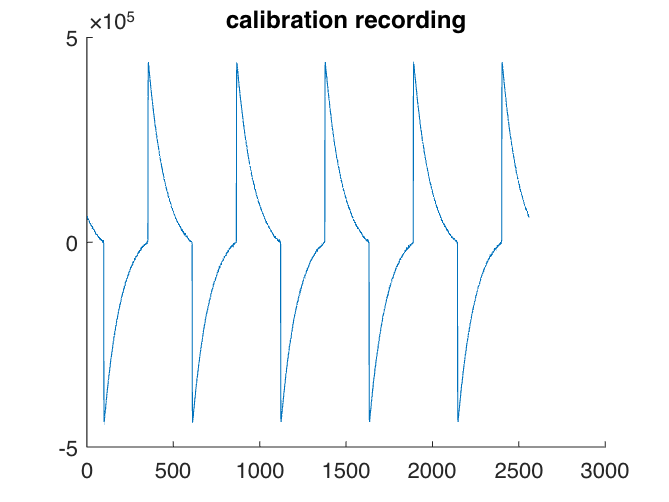

addpath(genpath('signals'))
addpath('signal_proc_functions')

% calstr is a variable containing the recording of the calibration signal.
load('calstr.mat', 'cal')
sample_rate = 256;

% rename cal variable and zero
data = cal;
data = data - mean(data);

% plot calibration signal
figure; hold('on')
title('calibration recording')
plot(data)


% find peaks of step response and plot 
[pks, i_pks] = findpeaks(...
    data, ...
    'MinPeakDistance', 500, 'MinPeakHeight', 2000)

pks = 	1.0e+05 *

    4.3810    4.3753    4.3919    4.3836    4.3893


i_pks =          356         868        1380        1892        2404


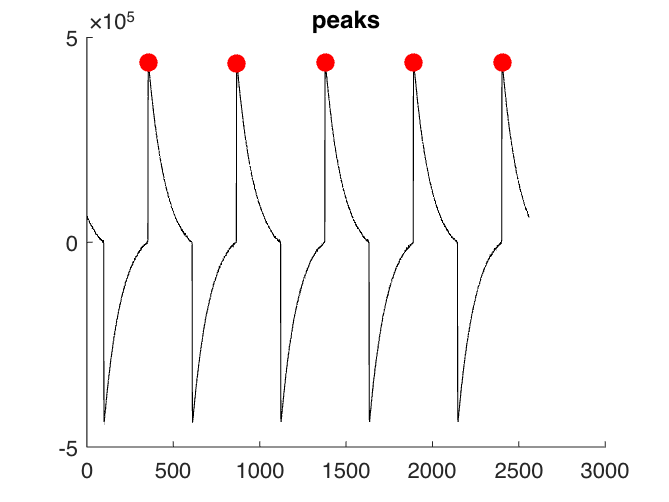


figure; hold('on')
title('peaks')
plot(data, 'k')
plot(i_pks, pks, 'r.', 'MarkerSize', 25)

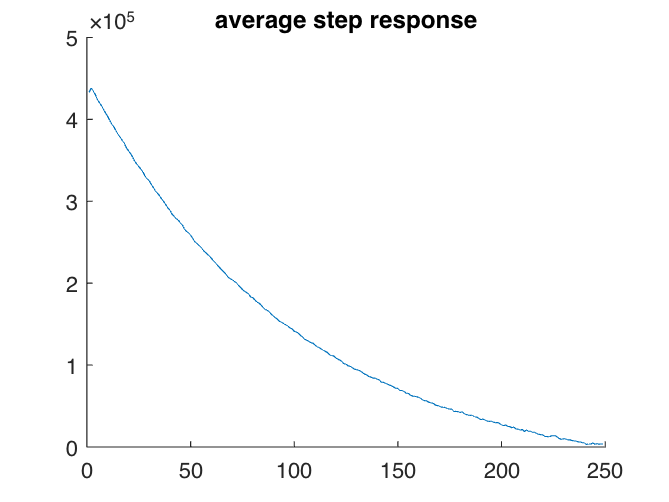

% Clip will start 1 sample before peak, end 247 after peak
front_flank = 1;
back_flank = 247;
n_clips = length(i_pks);

clips = nan(n_clips, front_flank + back_flank + 1);

for i = 1:4

    clips(i,:) = data(i_pks(i) - front_flank:i_pks(i) + back_flank);

end

% Average 4 recorded step responses and plot
step_response = mean(clips(1:4,:),1);

figure; hold('on')
title('average step response')
plot(step_response)

% Model step response with a 9th order polynomial
% y is the function to be fitted using polyfit. Start from index 2 to
% capture only the downward slope of the step response. Pad with zeros at
% the end for stability

y = [step_response(2:end), zeros(1, 16)];
x = 1:length(y);
norm_x = (x-mean(x))/std(x);

fittedmodel = fit(norm_x', y', 'poly9')

fittedmodel =      Linear model Poly9:
     fittedmodel(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =       130.8  (-124.2, 385.7)
       p2 =       -47.1  (-267.7, 173.5)
       p3 =      -313.3  (-1938, 1311)
       p4 =       512.1  (-729.3, 1754)
       p5 =      -469.8  (-3970, 3030)
       p6 =       787.3  (-1441, 3016)
       p7 =       -8890  (-1.18e+04, -5977)
       p8 =   3.797e+04  (3.66e+04, 3.935e+04)
       p9 =  -9.874e+04  (-9.95e+04, -9.797e+04)
       p10 =   9.004e+04  (8.983e+04, 9.025e+04)

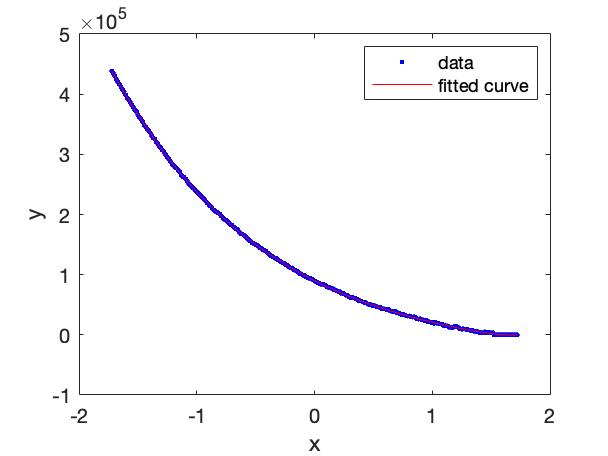


% Plot polyfit results
figure
plot(fittedmodel, norm_x, y)

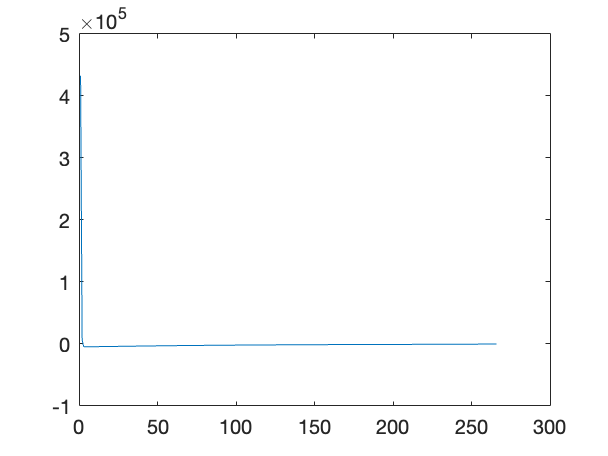


% Make curve using polyfit results
curve = ...
    fittedmodel.p1 * norm_x.^9 + ...
    fittedmodel.p2 * norm_x.^8 + ...
    fittedmodel.p3 * norm_x.^7 + ...
    fittedmodel.p4 * norm_x.^6 + ...
    fittedmodel.p5 * norm_x.^5 + ...
    fittedmodel.p6 * norm_x.^4 + ...
    fittedmodel.p7 * norm_x.^3 + ...
    fittedmodel.p8 * norm_x.^2 + ...
    fittedmodel.p9 * norm_x + ...
    fittedmodel.p10;

% make approximate step response by reintroducting the initial upward phase
% and padding with zeros at end
curve = [step_response(1), curve(1:257), zeros(1,8)];


% differentiate fitted step response to get UIR and plot
unit_impulse_response = diff([0, curve]);

figure
plot(unit_impulse_response)

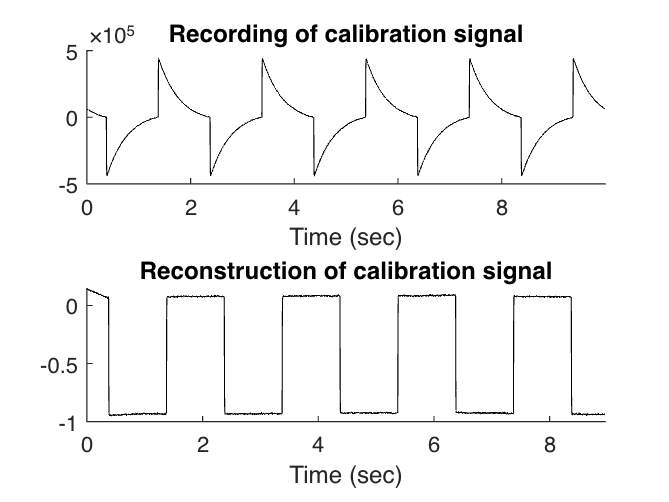

% test UIR by deconvolving calibration recording. Should generate a
% function that resembles a square wave 
recon = deconv(data, unit_impulse_response);

figure

subplot(2,1,1); hold('on')
title('Recording of calibration signal')
plot_signal(data, sample_rate, 'sec', 'k')

subplot(2,1,2); hold('on')
title('Reconstruction of calibration signal')
plot_signal(recon, sample_rate, 'sec', 'k')